face1 = [0 1 1 0]

face1 =      0     1     1     0


face2 = [0.1,0.9,0.8,0.2]

face2 =     0.1000    0.9000    0.8000    0.2000


face3 = [0.2,0.9,0.8,0.2]

face3 =     0.2000    0.9000    0.8000    0.2000


face4 = [0.1,0.8,0.9,0.2]

face4 =     0.1000    0.8000    0.9000    0.2000


face5 = [0.2,0.8,0.9,0.1]

face5 =     0.2000    0.8000    0.9000    0.1000



faces = {face1 face2 face3 face4 face5}

faces = 1×5 cell array
    {[0 1 1 0]}    {[0.1000 0.9000 0.8000 0.2000]}    {[0.2000 0.9000 0.8000 0.2000]}    {[0.1000 0.8000 0.9000 0.2000]}    {[0.2000 0.8000 0.9000 0.1000]}


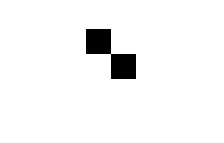

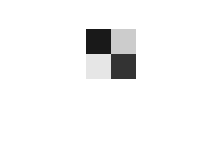

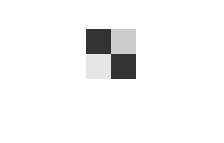

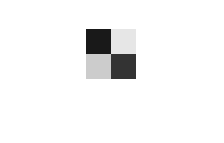

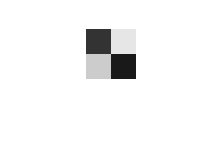




[a,b] = size(faces);
for c = 1:b
    f = faces{c};
    f = reshape(f, [2,2]);
    figure;
    imshow(f, 'InitialMagnification', 2500);
end



% random_images = {}
% for i= 1:20
%     random_images{i} = random()
% end




% [a,b] = size(random_images);
% for c = 1:b
%     f = random_images{c};
%     f = reshape(f, [2,2]);
%     figure;
%     imshow(f);
% end


D = Discriminator();
G = Generator();
D.weights

ans =    -0.4063   -1.6891   -1.5324   -0.0194


D.bias

ans = 1.3705

G.weights

ans =    -1.7449    0.1822   -1.8651   -1.5135


G.bias

ans =    -0.7843    0.3215   -0.6166   -1.4518



lr = 0.01;
epochs = 3000;

d_error = [];
g_error = [];

dd = [];
dn = {};
s = {};
d= []


d =

     []



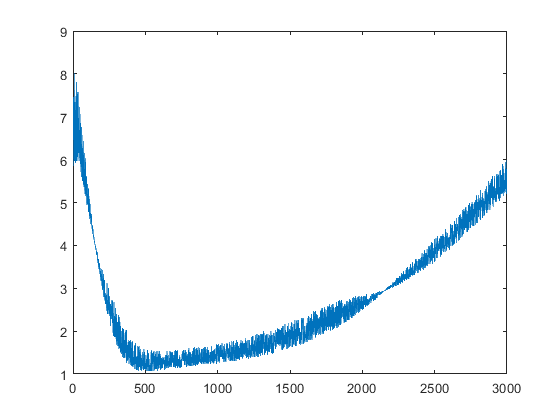

[m,n] = size(faces);
for i = 1:epochs
    for j = 1:n
       D.update(faces{j}, lr);
       z = 0 + rand*(1-0);
       su= sumM(D.error(faces{j}), D.noise_error(z));
       dd(i) = D.error(faces{j});
       dn{i} =  D.noise_error(z);
       s{i} = sumM(D.error(faces{j}), D.noise_error(z));
       d_error(i) = sum(su);
       g_error(i) = G.error(z,D);
       noise = G.forward(z);
       D.noise_update(noise, lr,D);
       G.update(z, D, lr);
    end
    
end


figure
plot(d_error)

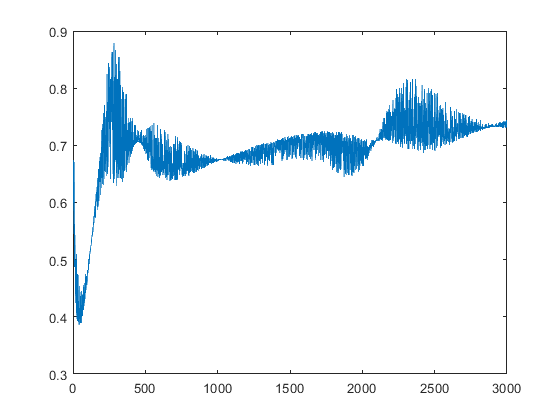

figure
plot(g_error)



images = {}


images =

  0×0 empty cell array




for i =1:7
    z=normrnd(-1,1);
    g_i = G.forward(z)
    images{i} = g_i
end

g_i =     0.0858    0.9721    0.9595    0.1992


images = 1×1 cell array
    {[0.0858 0.9721 0.9595 0.1992]}


g_i =     0.7291    0.7778    0.9579    0.6773


images = 1×2 cell array
    {[0.0858 0.9721 0.9595 0.1992]}    {[0.7291 0.7778 0.9579 0.6773]}


g_i =     0.2162    0.9434    0.9590    0.3303


images = 1×3 cell array
    {[0.0858 0.9721 0.9595 0.1992]}    {[0.7291 0.7778 0.9579 0.6773]}    {[0.2162 0.9434 0.9590 0.3303]}


g_i =     0.3696    0.9086    0.9587    0.4434


images = 1×4 cell array
    {[0.0858 0.9721 0.9595 0.1992]}    {[0.7291 0.7778 0.9579 0.6773]}    {[0.2162 0.9434 0.9590 0.3303]}    {[0.3696 0.9086 0.9587 0.4434]}


g_i =     0.2169    0.9432    0.9590    0.3310


images = 1×5 cell array
    {[0.0858 0.9721 0.9595 0.1992]}    {[0.7291 0.7778 0.9579 0.6773]}    {[0.2162 0.9434 0.9590 0.3303]}    {[0.3696 0.9086 0.9587 0.4434]}    {[0.2169 0.9432 0.9590 0.3310]}


g_i =     0.9874    0.2578    0.9562    0.9471


images = 1×6 cell array
    {[0.0858 0.9721 0.9595 0.1992]}    {[0.7291 0.7778 0.9579 0.6773]}    {[0.2162 0.9434 0.9590 0.3303]}    {[0.3696 0.9086 0.9587 0.4434]}    {[0.2169 0.9432 0.9590 0.3310]}    {[0.9874 0.2578 0.9562 0.9471]}


g_i =     0.4652    0.8835    0.9585    0.5059


images = 1×7 cell array
    {[0.0858 0.9721 0.9595 0.1992]}    {[0.7291 0.7778 0.9579 0.6773]}    {[0.2162 0.9434 0.9590 0.3303]}    {[0.3696 0.9086 0.9587 0.4434]}    {[0.2169 0.9432 0.9590 0.3310]}    {[0.9874 0.2578 0.9562 0.9471]}    {[0.4652 0.8835 0.9585 0.5059]}


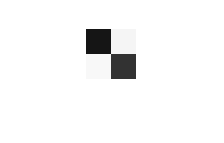

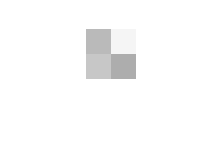

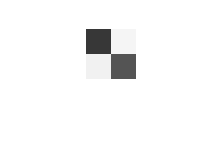

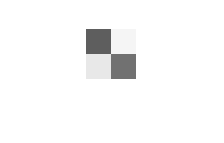

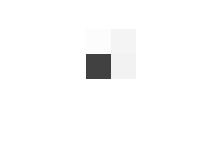

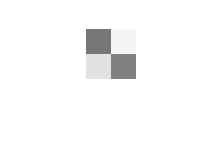



[o,p] = size(images);
for c = 1:p
    f = images{c};
    f = reshape(f, [2,2]);
    figure;
    imshow(f,'InitialMagnification', 2500);
end



G.weights

ans =    -2.1225    1.4537    0.0261   -1.3491


G.bias

ans =    -1.8377    3.1894    3.1598   -1.0560


D.weights

ans =    -0.4643   -0.4791   -0.7013    0.3892


D.bias

ans = 1.0105

function m = random()
m = [];
for i = 1:4
    val = 0 + rand*(1-0);
    m(i)= val;
end
end

function c = sumM(x, a)
for i = 1: size(a,1)
    a(i) = a(i)+x;
end
c=a;
end


